# Q2

A = [-0.2 2 2 0;
    0 -1 0 0;
    0 0 -2 0;
    0 0 0 -10];
B = [2 1 0;
    40 20 -20;
    60 30 -30;
    -2 -1 -3];
C = [1 0 0 -1;
    3 0 0 -3;
    0 1 1 0];
D = [0 0 0.9487;
    0 0 -0.3162;
    -0.4472 0.8944 0];
P = ss(A,B,C,D);
nmeas = 1;
ncont = 1;
K = h2synthesis(P,nmeas,ncont);


[K2,CL,GAM2] = h2syn(P,nmeas,ncont)

K2 =
 
  A = 
           x1      x2      x3      x4
   x1    -0.2  -2.202  -2.202       0
   x2  -61.96  -57.55  -55.94   23.17
   x3  -92.94  -84.24  -85.32   34.76
   x4  -9.294  0.2181  0.3104  -6.524
 
  B = 
           u1
   x1   4.202
   x2   44.32
   x3    65.9
   x4  -2.052
 
  C = 
           x1      x2      x3      x4
   y1   3.098  0.6114  0.5807  -1.159
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


CL =
 
  A = 
           x1      x2      x3      x4      x5      x6      x7      x8
   x1    -0.2       2       2       0       0       0       0       0
   x2       0      -1       0       0  -61.96  -12.23  -11.61   23.17
   x3       0       0      -2       0  -92.94  -18.34  -17.42   34.76
   x4       0       0       0     -10  -9.294  -1.834  -1.742   3.476
   x5       0   4.202   4.202       0    -0.2  -2.202  -2.202       0
   x6       0   44.32   44.32       0  -61.96  -57.55  -55.94   23.17
   x7       0    65.9    65.9       0  -92.94  -84.24  -85.3

GAM2 = 20.7369

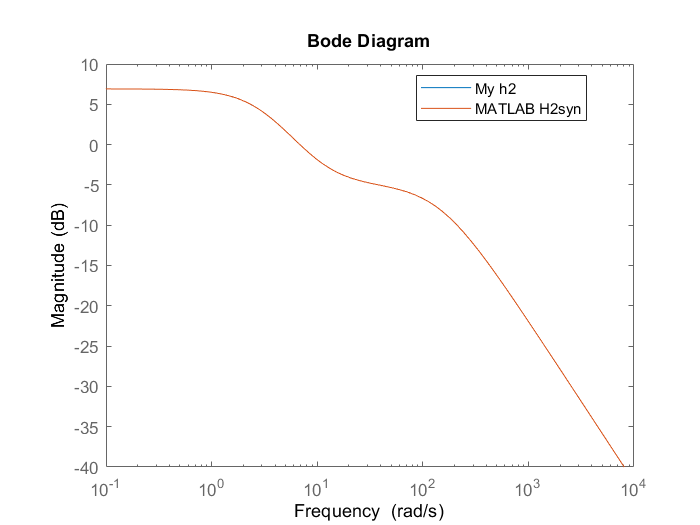

bodemag(K,K2)
legend("My h2","MATLAB H2syn","Location","best")

function K = h2synthesis(P,nmeas,ncont)
    A = P.A;
    B = P.B;
    C = P.C;
    D = P.D;
    B1 = B(:,1:end-ncont);
    B2 = B(:,end-ncont+1:end);
    C1 = C(1:end-nmeas,:);
    C2 = C(end-nmeas+1:end,:);
    D11 = D(1:end-nmeas,1:end-ncont);
    D12 = D(1:end-nmeas,end-ncont+1:end);
    D21 = D(end-nmeas+1:end,1:end-ncont);
    D22 = D(end-nmeas+1:end,end-ncont+1:end);
    B_are_1 = -B2*inv((D12')*D12)*(B2');
    C_are_1 = (C1')*C1;
    B_are_2 = -(C2')*inv(D21*(D21'))*C2;
    C_are_2 = B1*(B1');
    X = are_sol(A,B_are_1,C_are_1);
    Y = are_sol(A',B_are_2,C_are_2);
    Kopt = -inv((D12')*D12)*B2'*X;
    Lopt = Y*(C2')*inv(D21*(D21'));
    A_opt = A + B2*Kopt - Lopt*C2;
    B_opt = Lopt;
    C_opt = Kopt;
    [~,dcol] = size(B_opt);
    [drow,~] = size(C_opt);
    D_opt = zeros(drow,dcol);
    K = ss(A_opt,B_opt,C_opt,D_opt);
end

function X = are_sol(A,R,Q)
    H = [A R;
         -Q -A'];
    [V,J] = jordan(H);
    VV = [];
    lam = eig(A);
    % Check if pair (A,R) is stabilizable 

    
    for i = 1:length(lam)
        if real(lam(i)) > 0
        
        if rank([lam(i)*eye(length(A))-A,R]) ~= length(A)
            error('(A,R) is not stabilizable');  
        end
    end
    end
    
    % Check if R is positive/negative definite
%    lam_R = eig(R);
%     if (~all(real(lam_R))>0) || (~all(real(lam_R))<0)
%         error('R is not positive/negative definite');
%     end
    
    % Check if the eigen values of H lie on imaginary axis
    
    for i = 1:length(J)
         if real(J(i,i))<1e-14 && real(J(i,i))>-1e-14
            error('No solution: eigen value lies on imaginary axis');     
        
        elseif real(J(i,i))<0
            VV = [VV V(:,i)];
        end
        i = i+1;
    end
    VV = VV.';
    [R,p] = rref(VV);
    x1 = VV(:,p).';
    q = setdiff(1:size(VV,2),p);
    x2 = VV(:,q).';
    X = x2*inv(x1);
end
